# Check Parameters Computed from Small Run

We do a run with only 1000 molecules for only 10^6 steps and now check to see whether the computations for the correlation dimension and the growth rate are relatively similar to those computed in the larger runs.

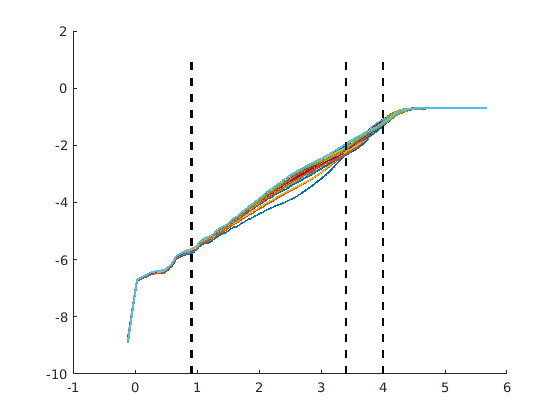

fileLocation = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/hoomd/patchy/analyze/optimize_runs/';
AAnames = {'250'};
SCnames = {'02'};
Signames = {'150'};
Rnames = Signames;
tframes = [210:200:3999 3999];
addpath('/home/rachael/Analysis_and_run_code/lab_notebook/CG_patchy/helper_fcns');
dataCell = readFractalDim(tframes,AAnames,SCnames,Signames,fileLocation);
fdimts = dataCell{1}{1}{1};
figure()
hold on
for ti = 1:size(fdimts,3)
    fdim = fdimts(:,:,ti);
    plot(log(fdim(:,1)),log(fdim(:,2)),'linewidth',2)

end
plot(log(2.5)*ones(size(-10:1)),-10:1,'--k','linewidth',2)
plot(log(30.1)*ones(size(-10:1)),-10:1,'--k','linewidth',2)
plot(4*ones(size(-10:1)),-10:1,'--k','linewidth',2)

## Check Dimension in Regime III

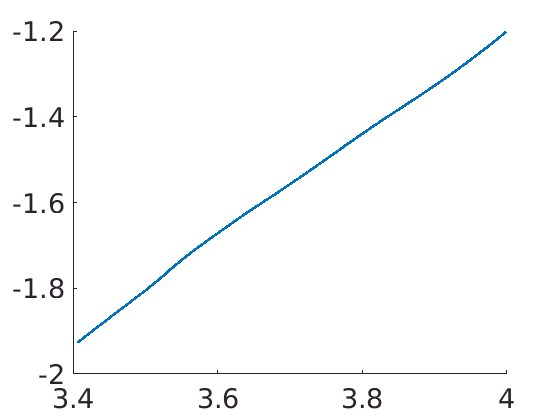

i3start = find(abs(fdim(:,1)-30.1)==min(abs(fdim(:,1)-30.1)));
i3end = find(abs(fdim(:,1)-exp(4))==min(abs(fdim(:,1)-exp(4))));
figure()
hold on
plot(log(fdim(i3start:i3end,1)),log(fdim(i3start:i3end,2)),'linewidth',2)
lf = fittype('a*x+b','independent','x');
set(gca,'fontsize',20)

[P1,gP1] = fit(log(fdim(i3start:i3end,1)),log(fdim(i3start:i3end,2)),lf);

The dimension is slightly lower, because we have not run the simulation for as long, probably.  I will need to think about whether this means we should run for the full length of time and just on the smaller box (~5 hours, 2 cores, BW), or whether this is all right.  It is possible we do not need to be fully comparable to the full runs anyways.

## Check Dimension in Regime II

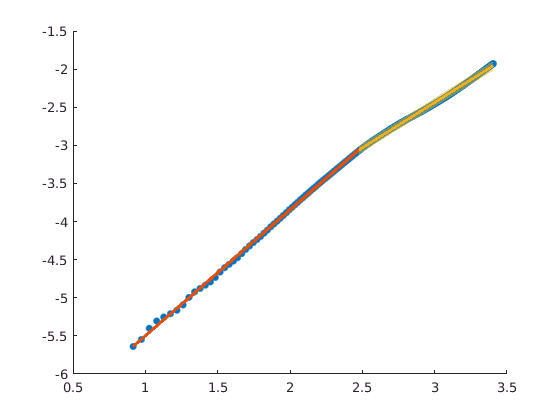

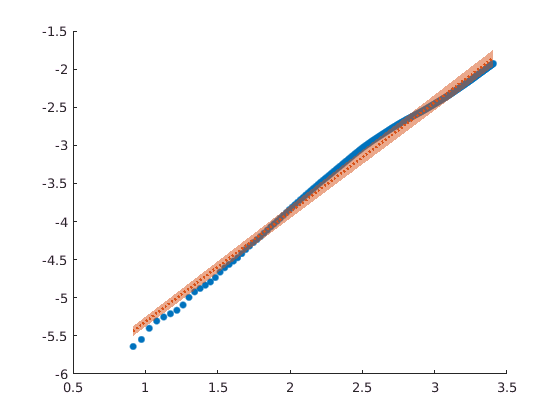

i2start = find(abs(fdim(:,1)-2.5)==min(abs(fdim(:,1)-2.5)));
i2end = i3start;
[l1,l2,splt,lsing,aic1,aic2,fig1,fig2] = Lmethod(log(fdim(i2start:i2end,1)),log(fdim(i2start:i2end,2)),[],0,0);

It seems as if we're getting lower dimensions--which, again, is *maybe* fine?  The question is whether it's still comparable.  Hmmmmm.  Gotta continue to think about this.  Certainly the length scales are on the order of interstitial spaces in this run...

## Check Growth Rates

Each frame step is 165 ns.

Cut off the first 120 frames (=19.8 microseconds).

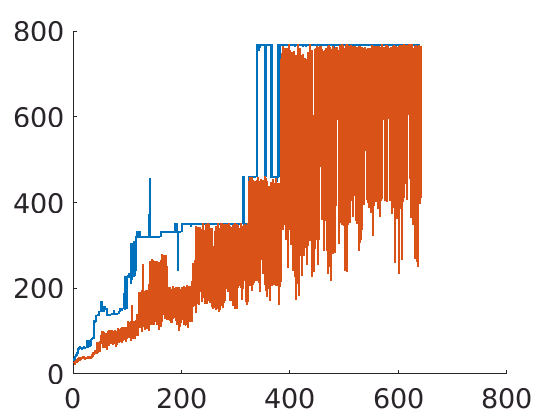

tstart = 120; %cut off timesteps
fr2mus = 165/1000;
fileLocation = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/hoomd/patchy/analyze/optimize_runs/';
AAnames = {'250'};
SCnames = {'02'};
Signames = {'150'};
fbase = 'mols10000_';
i=1;
sc = 1;
sig = 1;
foldname = [fileLocation AAnames{i} '-' SCnames{sc} '-' Signames{sig} '/'];
fname = [foldname fbase AAnames{i} '-' SCnames{sc} '-' Signames{sig} '_run-contact-mu2s.dat'];
fnameo = [foldname fbase AAnames{i} '-' SCnames{sc} '-' Signames{sig} '_run-optical-mu2s.dat'];  
dataMatrix = importdata(fname);
dataMatrix = dataMatrix(tstart:end,:);

dataMatrixo = importdata(fnameo);
dataMatrixo = dataMatrixo(tstart:end,:);

figure()
hold on
ts = (0:(length(dataMatrix)-1))*fr2mus;
plot(ts,dataMatrix,'linewidth',2)
plot(ts,dataMatrixo,'linewidth',2)
set(gca,'fontsize',20)

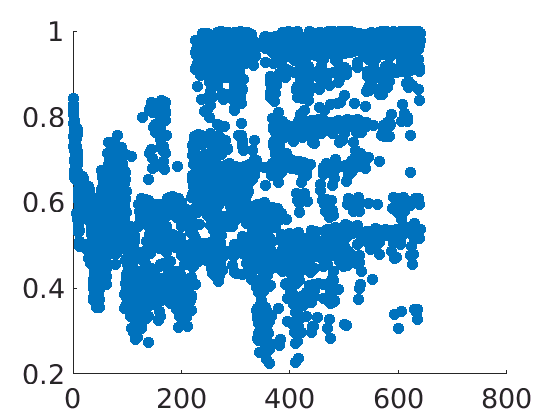


figure()
hold on
set(gca,'fontsize',20)
plot(ts,dataMatrixo./dataMatrix,'linewidth',2)